BASE_DIR='/Users/erik/Dropbox/Projects/Machine_Learning/data/'

BASE_DIR = '/Users/erik/Dropbox/Projects/Machine Learning/data/'

m = 1;
b = 10;
N = 40;
y=zeros(1,N);

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


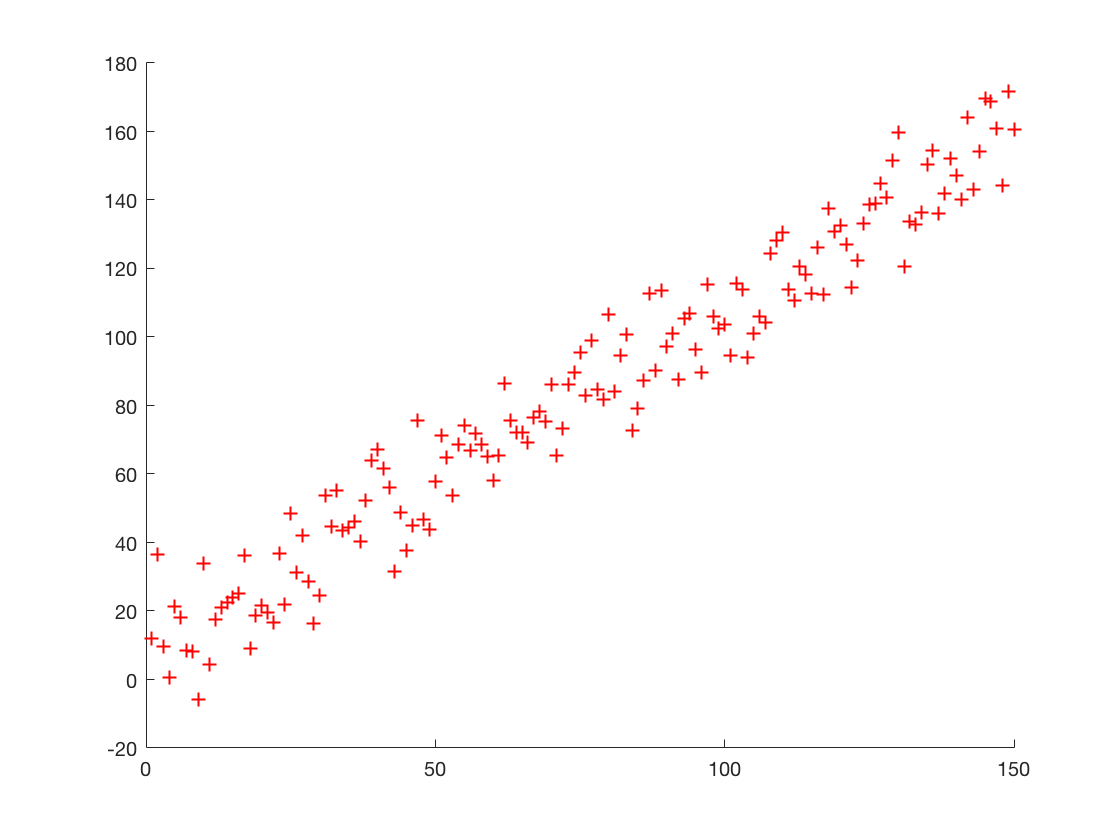

for x = 1:N
    mu=m*x+b;
    sigma = 2;
    
    % values are true + noise
    y(x) = normrnd(mu,sigma,1);
end

figure(1);
scatter(1:N,y,'r+');



X=horzcat((1:N)',y');

X =     1.0000   12.1033
    2.0000   36.6068
    3.0000    9.6271
    4.0000    0.5605
    5.0000   21.4317
    6.0000   18.2017
    7.0000    8.3806
    8.0000    8.0955
    9.0000   -5.9796
   10.0000   33.8054


csvwrite(BASE_DIR+"line.csv",X)
